filename = 'Servo_Latency_Response_Data.xlsx'; 
data = readtable(filename);

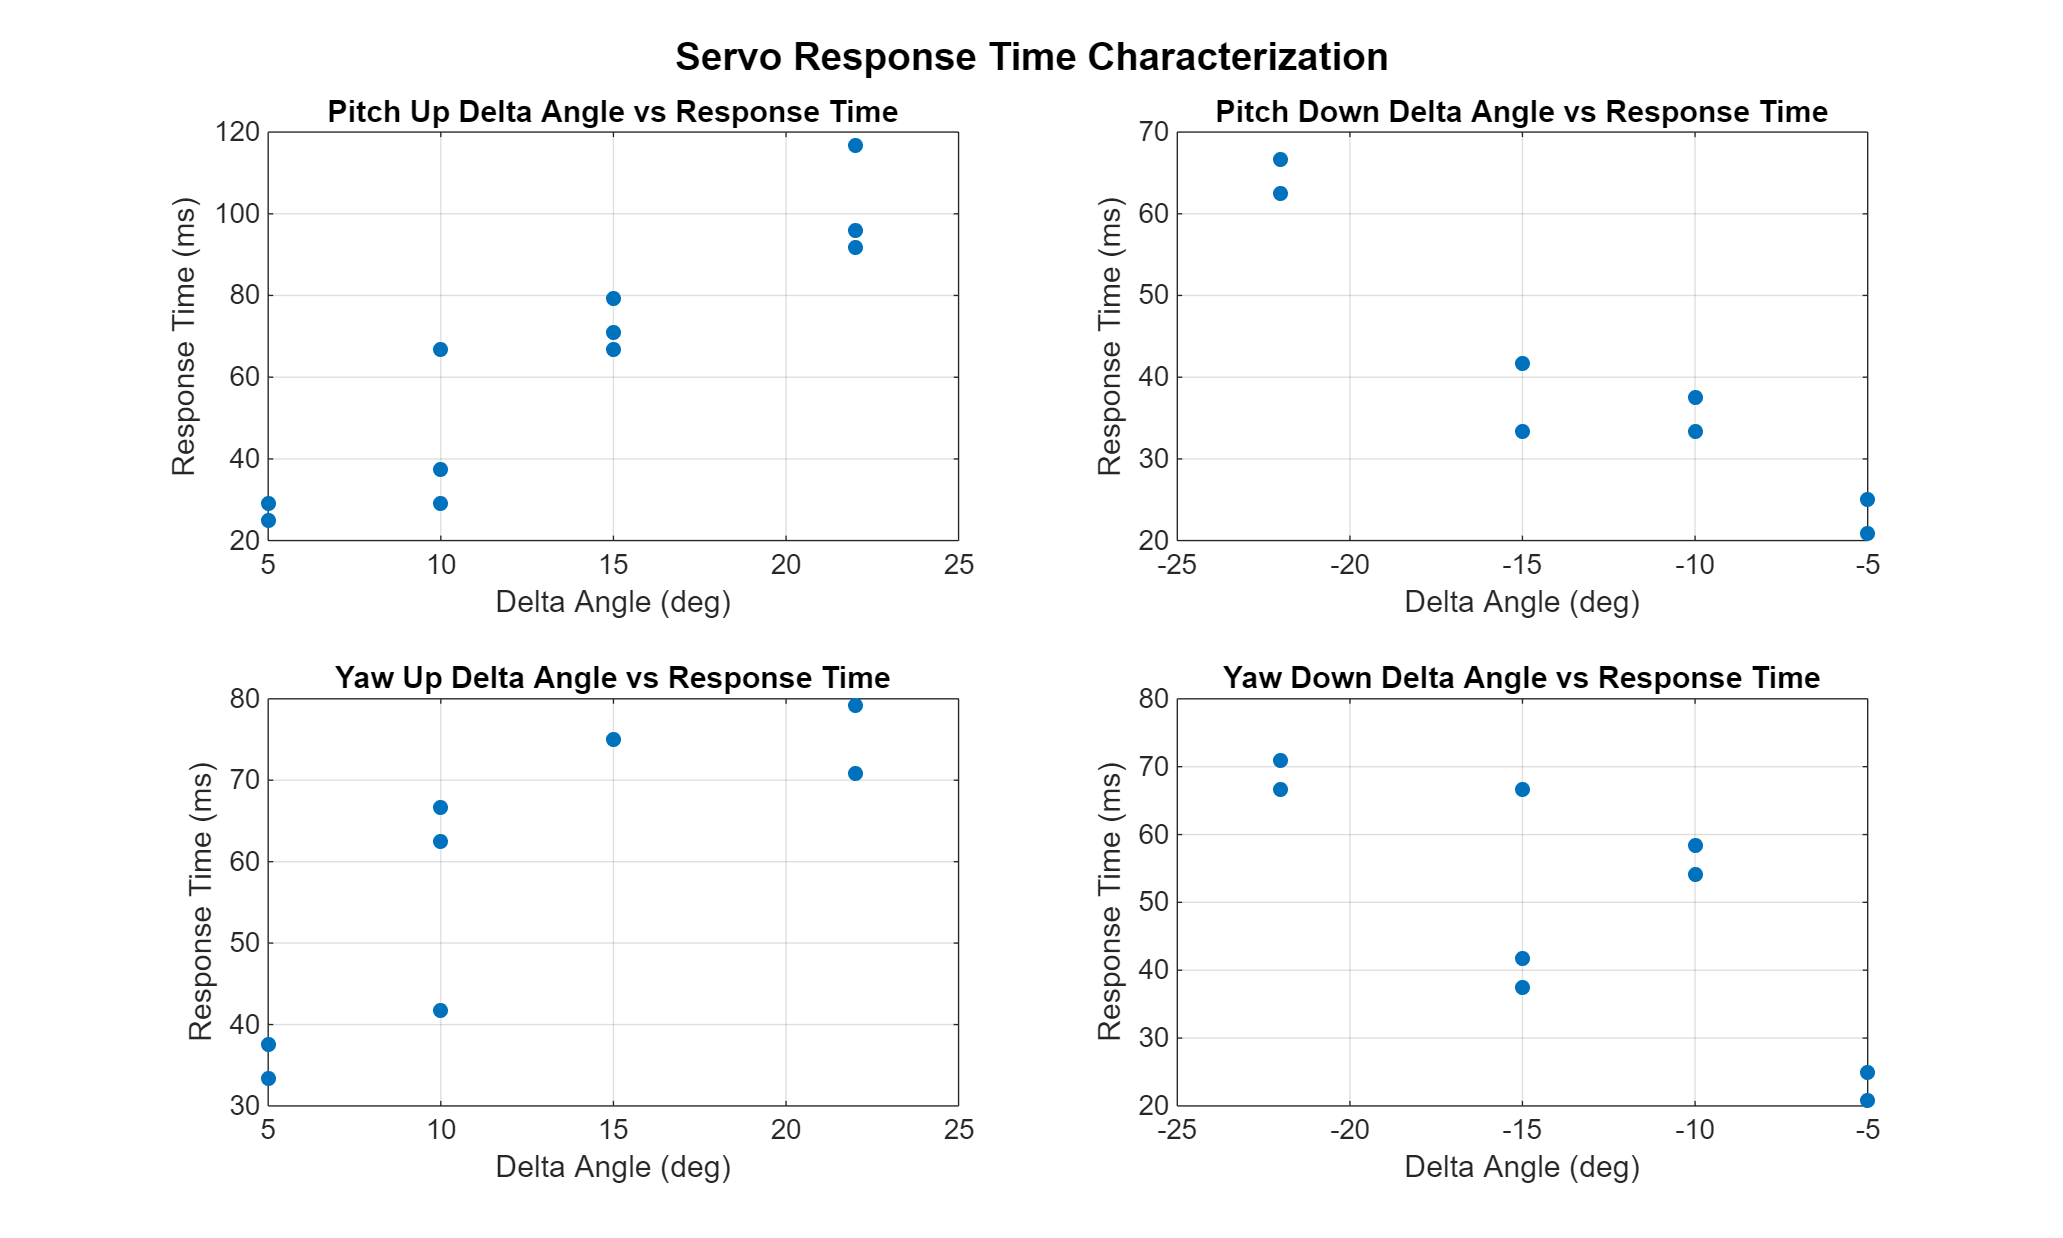


pitchData = data(strcmpi(data.Axis,'Pitch'),:);
yawData   = data(strcmpi(data.Axis,'Yaw'),:);

% Split into up/down
pitchUp   = pitchData(pitchData.DeltaAngle > 0,:);
pitchDown = pitchData(pitchData.DeltaAngle < 0,:);
yawUp     = yawData(yawData.DeltaAngle > 0,:);
yawDown   = yawData(yawData.DeltaAngle < 0,:);

%% Plot formatting
figure('Color','w','Position',[100 100 1000 600])

subplot(2,2,1)
scatter(pitchUp.DeltaAngle, pitchUp.ResponseTime_ms_,30,'filled')
title('Pitch Up Delta Angle vs Response Time','FontWeight','bold')
xlabel('Delta Angle (deg)')
ylabel('Response Time (ms)')
grid on; box on;

subplot(2,2,2)
scatter(pitchDown.DeltaAngle, pitchDown.ResponseTime_ms_,30,'filled')
title('Pitch Down Delta Angle vs Response Time','FontWeight','bold')
xlabel('Delta Angle (deg)')
ylabel('Response Time (ms)')
grid on; box on;

subplot(2,2,3)
scatter(yawUp.DeltaAngle, yawUp.ResponseTime_ms_,30,'filled')
title('Yaw Up Delta Angle vs Response Time','FontWeight','bold')
xlabel('Delta Angle (deg)')
ylabel('Response Time (ms)')
grid on; box on;

subplot(2,2,4)
scatter(yawDown.DeltaAngle, yawDown.ResponseTime_ms_,30,'filled')
title('Yaw Down Delta Angle vs Response Time','FontWeight','bold')
xlabel('Delta Angle (deg)')
ylabel('Response Time (ms)')
grid on; box on;

sgtitle('Servo Response Time Characterization','FontSize',14,'FontWeight','bold')